# Load ground truth

clc
close all
clear all
location = './bunny/data/gt_pose.txt';
gt_data = readmatrix(location)

gt_data =                    0                   0                   0                   0                   0                   0   1.000000000000000
  -0.052021100000000  -0.000383981000000  -0.010922300000000   0.005484490000000  -0.294635000000000  -0.003855500000000   0.955586000000000
   0.004351020000000   0.088286300000000  -0.108853000000000  -0.441019000000000   0.213083000000000   0.007057340000000   0.871807000000000
  -0.006460170000000  -0.000013612200000  -0.012906400000000   0.004492090000000   0.384220000000000  -0.009765120000000   0.923179000000000


% convert it to trasnformation
T_gt = {}


T_gt =

  0×0 empty cell array



for k=1:4
    t = [gt_data(k,1),gt_data(k,2),gt_data(k,3)];
    quat = [gt_data(k,7),gt_data(k,4),gt_data(k,5),gt_data(k,6)];
    rotm = inv(quat2rotm(quat));
    tform = rigidtform3d(rotm,t);
    T_gt{k} = tform;
end 

V1 = pcread('./bunny/data/bun000.ply');
V2 = pcread(['./bunny/data/bun045.ply']);
V5 = pcread(['./bunny/data/chin.ply']);
V6 = pcread(['./bunny/data/bun315.ply']);
V_p = {V1,V2,V5,V6};
V={}


V =

  0×0 empty cell array



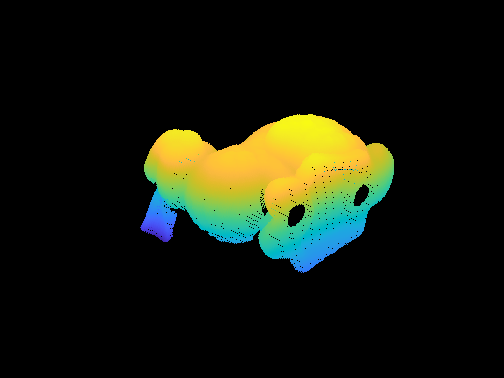

hold on
resultFolder = {'example1.pcd','example2.pcd','example3.pcd','example4.pcd'};
for k = 1:4
    V_p{k} = pctransform(V_p{k},T_gt{k});
    pcshow(V_p{k})
    V{k} = V_p{k}.Location';
    pcwrite(V_p{k},resultFolder{k},'Encoding','ascii');
    
end
    
hold off

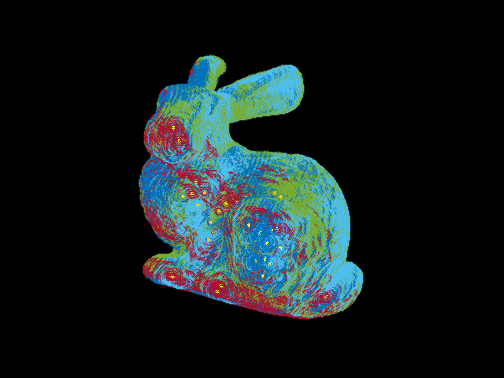

Error using matlab.graphics.axis.Axes/set
Children may only be set to a permutation of itself.

figure(2);
hold on,grid on

% make the legend
title('Initial position of the point clouds','fontweight','bold','fontsize',12);

hg1 = cellfun(@(V)  scatter3(V(1,:),V(2,:),V(3,:)),V);

%set(1,'position',get(1,'position')+[-260 0 0 0]);

set(gca,'fontweight','bold','children',hg1);


view([40 54]) 
% scatter3(Xin(1,:),Xin(2,:),Xin(3,:),'k')
hold off; drawnow